clc;
clear;

Calculando o Tau e o Kcc

opts = detectImportOptions('dados_aquecedor_matlab.csv');
T = readtable('dados_aquecedor_matlab.csv', opts);
time = T.time;
temp_offset = T.temp_offset;

% Achando tau e o ganho Kcc
stable_temperature = 26.0;
aux_temp = stable_temperature * 0.632; 
[~, idx] = min(abs(temp_offset - aux_temp));
tau = time(idx);
Kc = stable_temperature/0.015;
disp(['Tau: ', num2str(tau)]);

Tau: 930


disp(['Kcc: ', num2str(Kc)]);

Kcc: 1733.3333


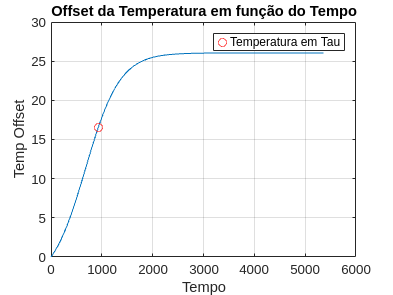



plot(time, temp_offset);
hold on;
temp_offset_at_tau = temp_offset(idx);
plot(tau, temp_offset_at_tau, 'ro'); % Destacar o ponto
title('Offset da Temperatura em função do Tempo');
legend('', 'Temperatura em Tau');
xlabel('Tempo');
ylabel('Temp Offset');
grid on;
hold off;

Achando a função de transferencia

s = tf('s');

% Kcc = Resistencia Termica
% Tau = Resistencia Termica * Capacitancia Termica
G = Kc / (tau*s + 1)


G =
 
    1733
  ---------
  930 s + 1
 
Continuous-time transfer function.
Model Properties


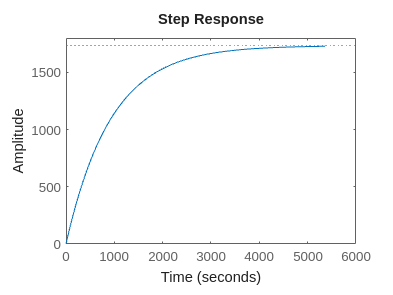

step(G, time);

Aplicando o Ganho da Potencia Elétrica pelo relé e Ganho Kph

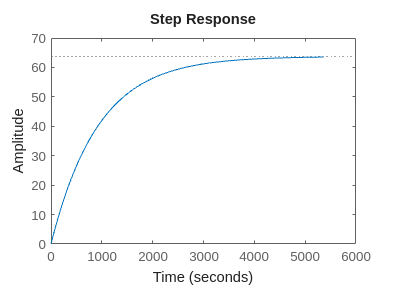

Kcc = 127^2/6.5; % chechar no atigo ganho do rele
Kr = 1/16.129;
Kph = 2.39 * 10^(-4);
K = Kcc * Kr * Kph;
step(K * G, time);

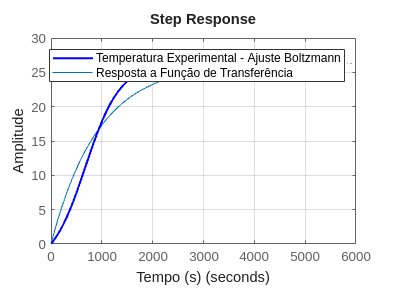


figure;
plot(time, temp_offset, 'b', 'LineWidth', 1.5); % Plota o sinal contínuo
hold on;
Kpe = 32^2 / 16.129;
step(Kpe * Kph * G, time);
hold off;

xlabel('Tempo (s)');
ylabel('Amplitude');
title('Step Response');
legend('Temperatura Experimental - Ajuste Boltzmann', 'Resposta a Função de Transferência');
grid on;

Fazendo o controlador PI

tempo_assentamento = 4 / (amortecimento * omega_n)

Gc = Kp * ( 1 + (1 / (Ti * s) ) )

K_total = 0.1 * K % K_sensor * K

K_total = 0.0037

K_total * G


ans =
 
    6.373
  ---------
  930 s + 1
 
Continuous-time transfer function.
Model Properties



Gmf = feedback(K * G, 0.1);
info = stepinfo(Gmf);
tempo_assentamento = info.SettlingTime

tempo_assentamento = 493.4307


% 0.00685268817 / (1 * s + 0.00107526881 )
% zero do controlador em -0.00107526881
zero = -0.00107526881

zero = -0.0011

% sistema deve ter 0 overshoot (amortecimento = 1)
amortecimento = 1

amortecimento = 1

omega_n = 4 / (amortecimento * tempo_assentamento)

omega_n = 0.0081

polo_mf = -1 * amortecimento * omega_n

polo_mf = -0.0081


syms Kp 
s_aux = polo_mf

s_aux = -0.0081

eq = abs(Kp * ((s_aux - zero) / s_aux) * (0.00685268817 / (1 * s_aux + 0.00107526881 ))) == 1;
Kp_sol = solve(eq, Kp)

$$Kp\_sol = \frac{2535301200456458802993406410752}{2143170544916072350357736897455}$$

Kp = 1.18296754613

Kp = 1.1830


Gc = ((s - zero) / s)


Gc =
 
  s + 0.001075
  ------------
       s
 
Continuous-time transfer function.
Model Properties



Gmfc = feedback(Gc * K * G, 0.1);
info = stepinfo(Gmfc);
tempo_assentamento = info.SettlingTime

tempo_assentamento = 570.8519

Circuito de Gc

Kp = 1.183;
Ti = 930;

syms R2 R4

C1 = 1000 * 10 ^ (-6)

C1 = 1.0000e-03

R1 = 500 * 1000

R1 = 500000

R3 = 50 * 1000

R3 = 50000


eq1 = Ti == R2 * C1;
eq2 = Kp == (R2 * R4) / (R1 * R3);
sol = solve([eq1, eq2], [R2, R4]);
double(sol.R2)

ans = 930000

double(sol.R4)

ans = 3.1801e+04